# Quantitative Methods for Finance

2025 Marina Dolfin

# **QMF2_1_Modelling_Optimization**

## **Optimal Asset Allocation within the Mean–Variance Portfolio Framework**

**(A short theoretical background is provided at the end of the Live Script.)**

This activity illustrates how to construct and analyze a mean–variance optimal portfolio using MATLAB's Portfolio object.

You will learn how to:

Fetch and prepare daily price data for a small set of large, liquid stocks across different sectors.

Compute daily returns and estimate expected returns and covariances.

Define portfolio constraints and estimate the portfolio that maximizes the Sharpe Ratio.

Visualize the efficient frontier and evaluate portfolio performance in risk–return space.

This exercise provides a hands-on demonstration of the principle of diversification: when assets from different sectors move differently, portfolio risk can be reduced for a given expected return.

We use a small set of **large, liquid stocks**.

They are widely traded, well known, and represent different sectors.

This allows us to demonstrate the principle of **diversification**: when sectors move differently, portfolio risk is reduced.

**Tech**

- Apple (`AAPL`)

- Microsoft (`MSFT`)

- Nvidia (`NVDA`)

- Alphabet Class A (`GOOGL`)

**Finance**

- JPMorgan Chase (`JPM`)

- Goldman Sachs (`GS`)

- HSBC Holdings (`HSBC`)

**Consumer**

- Coca-Cola (`KO`)

- Procter & Gamble (`PG`)

**Energy**

- ExxonMobil (`XOM`)

- Shell (`SHEL`)

% Define the number of trading days in a year
trading_days = 252;

 % Define annual risk-free rate (e.g., 5%)
rf_annual = 0.05;

% Convert to daily rate assuming 252 trading days
rf_daily = (1 + rf_annual)^(1/trading_days) - 1;

% Script to fetch and combine closing prices for multiple stock indices with interpolation

% List of stock index symbols
symbols = {'AAPL','MSFT','NVDA','GOOGL','JPM','GS','HSBC','KO','PG','XOM','SHEL'};


% Define the date range and parameters
startDate = '01-Jan-2025';
endDate = '01-Sep-2025';
interval = '1d';        % Daily data
fields = {'close'};     % Only closing prices

% Number of symbols
numSymbols = length(symbols);

% Cell arrays to store data
stockDataCell = cell(numSymbols, 1);
timetablesCell = cell(numSymbols, 1);

% Fetch data for each symbol and convert to timetable
for k = 1:numSymbols
    symbol = symbols{k};
    fprintf('Fetching data for %s...\n', symbol);
    
    try
        % Fetch data using the custom function
        stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields);
        
        % Remove time component and set dates to midnight
        stockData.Date = dateshift(stockData.Date, 'start', 'day');
        
        % Rename the 'Close' column to the symbol name
        varName = matlab.lang.makeValidName(symbol);
        stockData.Properties.VariableNames{'Close'} = varName;
        
        % Convert to timetable
        tt = table2timetable(stockData, 'RowTimes', 'Date');
        
        % Store the timetable
        timetablesCell{k} = tt(:, varName);  % Only include the price column
    catch ME
        warning('Failed to fetch data for %s: %s', symbol, ME.message);
        timetablesCell{k} = timetable();  % Empty timetable
    end
end

Fetching data for AAPL...
Fetching data for MSFT...
Fetching data for NVDA...
Fetching data for GOOGL...
Fetching data for JPM...
Fetching data for GS...
Fetching data for HSBC...
Fetching data for KO...
Fetching data for PG...
Fetching data for XOM...
Fetching data for SHEL...



% Remove empty timetables
nonEmpty = ~cellfun(@isempty, timetablesCell);
timetablesCell = timetablesCell(nonEmpty);
symbols = symbols(nonEmpty);

% Collect all unique dates from all indices
allDates = [];
for k = 1:length(timetablesCell)
    allDates = [allDates; timetablesCell{k}.Date];
end

% Get unique sorted dates
commonDates = unique(allDates);

% Sort dates
commonDates = sort(commonDates);

% Resample all timetables to the common dates with interpolation
for k = 1:length(timetablesCell)
    % Synchronize to common dates with linear interpolation
    timetablesCell{k} = retime(timetablesCell{k}, commonDates, 'linear');
end

% Combine all timetables into one
combinedTimetable = timetablesCell{1};
for k = 2:length(timetablesCell)
    combinedTimetable = synchronize(combinedTimetable, timetablesCell{k}, 'union', 'linear');
end

% Convert timetable to table
combinedData = timetable2table(combinedTimetable);

% Rename the time variable to 'Date'
combinedData.Properties.VariableNames{1} = 'Date';

% Display the first few rows
disp('Combined Data (First 10 Rows):');

Combined Data (First 10 Rows):


disp(head(combinedData, 10));

       Date         AAPL      MSFT      NVDA     GOOGL      JPM        GS      HSBC      KO        PG       XOM      SHEL 
    ___________    ______    ______    ______    ______    ______    ______    _____    _____    ______    ______    _____

    02-Jan-2025    243.85    418.58    138.31    189.43       240    574.97    48.68    61.84    165.98    107.31     63.1
    03-Jan-2025    243.36    423.35    144.47    191.79    243.28    580.13    49.07    61.75    165.13    107.86    64.52
    06-Jan-2025       245    427.85    149.43    196.87    240.85    583.39    49.27    60.81     1


% Write the combined data to an Excel file
writetable(combinedData, 'Data.xlsx');
fprintf('Data with interpolated missing values has been written to StockIndicesData_Interpolated.xlsx\n');

Data with interpolated missing values has been written to StockIndicesData_Interpolated.xlsx


convert into daily return


 dailyReturn = tick2ret(combinedData(2:end,2:end));




## Create the portfolio object



p = Portfolio('AssetList', symbols, 'RiskFreeRate', rf_daily);

p = estimateAssetMoments(p, dailyReturn)

p =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: 1.9363e-04
                     AssetMean: [11×1 double]
                    AssetCovar: [11×11 double]
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 11
                     AssetList: {'AAPL'  'MSFT'  'NVDA'  'GOOGL'  'JPM'  'GS'  'HSBC'  'KO'  'PG'  'XOM'  'SHEL'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: []
                    UpperBound: []
                   LowerBudget: []
                   UpperBudget: []
                 

We now impose the standard **default constraints** for our portfolio.

This corresponds to a **long-only, fully-invested** position, meaning:

- All portfolio weights are nonnegative (no short-selling).

- The total of all weights sums to one (all capital is invested).

p = setDefaultConstraints(p)

p =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: 1.9363e-04
                     AssetMean: [11×1 double]
                    AssetCovar: [11×11 double]
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 11
                     AssetList: {'AAPL'  'MSFT'  'NVDA'  'GOOGL'  'JPM'  'GS'  'HSBC'  'KO'  'PG'  'XOM'  'SHEL'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: [11×1 double]
                    UpperBound: []
                   LowerBudget: 1
                   UpperBudget: 1
        

The fully-invested, long-only constraints can be relaxed if desired. For example, allowing short-selling.

# Portfolio Performance Evaluation

## Evaluating  performance based on average return alone is not very useful. Returns must be adjusted for risk before they can be compared meaningfully. 

## Methods of risk-adjusted performance evaluation  using mean-variance criteria came on stage simultaneously with the capital asset pricing model. 

## One popular measure is the Sharpe Ratio:

## 
$$SR = \frac{\mathbb E[R_P]-R_f}{\sigma_P}$$


## that divides average portfolio excess return over the sample period by the standard deviation of returns over that period. 

## It measures the reward to (total) volatility trade-off. With mean-variance preferences, one wants to maximize the Sharpe ratio. 

## We want now to estimate the portfolio that is maximizing the Sharpe Ratio


w1 = estimateMaxSharpeRatio(p)

w1 =     0.0000
    0.2244
    0.0000
    0.0000
    0.0375
    0.0000
    0.4270
    0.3112
    0.0000
    0.0000
    0.0000




[risk1, ret1] = estimatePortMoments(p, w1);

% Annualize the returns
annualized_return = ret1 * trading_days

annualized_return = 0.3391


% Annualize the risk (standard deviation)
annualized_risk = risk1 * sqrt(trading_days)

annualized_risk = 0.1725

## **Data Visualization: plot the efficient frontier and risk and returns of assets**

Plot the risk and returns of the assets


scatter(sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.

xlabel('Risk')

ylabel('Expected Return')

text(sqrt(diag(cov))+0.0003,m,symbols,'FontSize',7); % Label ticker names

Plot optimal portfolio and efficient frontier using `plotFrontier in the same graphical window`

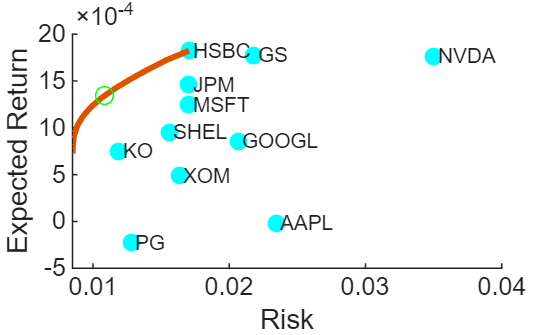

hold on;

[daily_risk, daily_return]  = plotFrontier(p,12);


plot(risk1,ret1,'og');

hold off

Extrapolate portolios' weights

pwgt = estimateFrontier(p,5)

pwgt =          0         0         0         0         0
    0.2083    0.2390    0.2407    0.1791         0
         0         0         0         0         0
    0.0702    0.0326         0         0         0
         0         0    0.0307    0.0563         0
         0         0         0         0         0
    0.0011    0.1199    0.3558    0.6237    1.0000
    0.4577    0.4971    0.3727    0.1409         0
    0.1128         0         0         0         0
    0.1272    0.0544         0         0         0
    0.0227    0.0570         0         0         0



[risk, ret] = estimatePortMoments(p, pwgt);
% Annualize the returns
annualized_return = ret * trading_days;

% Annualize the risk (standard deviation)
annualized_risk = risk * sqrt(trading_days);

% Display the results
fprintf('Annualized Return: %.2f%%\n', annualized_return * 100);

Annualized Return: 18.22%
Annualized Return: 25.14%
Annualized Return: 32.07%
Annualized Return: 38.99%
Annualized Return: 45.91%


fprintf('Annualized Risk (Standard Deviation): %.2f%%\n', annualized_risk * 100);

Annualized Risk (Standard Deviation): 13.49%
Annualized Risk (Standard Deviation): 13.93%
Annualized Risk (Standard Deviation): 16.24%
Annualized Risk (Standard Deviation): 20.78%
Annualized Risk (Standard Deviation): 27.06%


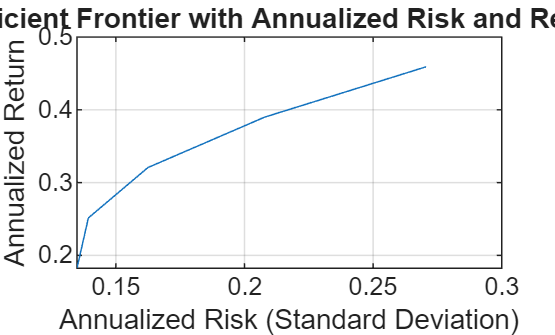


% Plot the annualized values if needed
figure;
plot(annualized_risk, annualized_return);
xlabel('Annualized Risk (Standard Deviation)');
ylabel('Annualized Return');
title('Efficient Frontier with Annualized Risk and Return');
grid on;

## Plot the profile for the Sharpe Ratio vs the efficient frontier

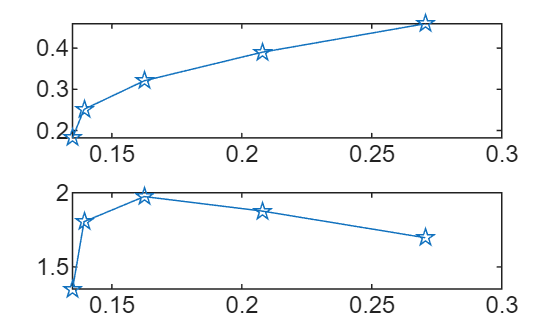



createfigure(annualized_risk,annualized_return,(annualized_return)./annualized_risk)

Once the Max Sharpe portfolio has been identified, you can extend the analysis by:

- Comparing it with an **equally weighted portfolio** or a **minimum-variance portfolio**.

- Exploring the impact of **short-selling constraints** or **sector limits**.

- Annualizing returns and risk to compare performance across strategies.

- Investigating **how the efficient frontier changes over time** using a rolling-window estimation approach.

These extensions provide a broader understanding of how diversification, constraints, and time variation influence portfolio efficiency and performance evaluation.

function createfigure(X1, Y1, ret1)
%CREATEFIGURE(X1, Y1, ret1)
%  X1:  vector of plot x data
%  Y1:  vector of plot y data
%  RET1:  vector of plot y data

%  Auto-generated by MATLAB on 22-Nov-2023 16:20:59

% Create figure
figure1 = figure;

% Create subplot
subplot1 = subplot(2,1,1,'Parent',figure1);
hold(subplot1,'on');

% Create plot
plot(X1,Y1,'Parent',subplot1,'Marker','pentagram');

box(subplot1,'on');
hold(subplot1,'off');
% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% Create plot
plot(X1,ret1,'DisplayName','ret2./risk2 vs risk2','Parent',axes1,...
    'Marker','pentagram');

box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'OuterPosition',[0 0.044043867415214 1 0.418608458079895]);
end


function stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
% fetchYahooFinanceData Fetches historical stock data from Yahoo Finance.
%
%   stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
%
%   Parameters:
%       symbol     - Stock symbol as a string (e.g., 'AAPL').
%       startDate  - Start date as a string or datetime ('dd-mmm-yyyy' format).
%       endDate    - End date as a string or datetime ('dd-mmm-yyyy' format).
%       interval   - Data interval: '1d' (daily), '1wk' (weekly), '1mo' (monthly).
%       fields     - Cell array of strings -i.e.curly brackets needed to
%       enter input, specifying data fields to retrieve, one or more
%                    Valid fields: 'open', 'close', 'high', 'low',
%                    'volume'. e.g.{'open', 'high', 'low', 'close', 'volume'}, 
%
%   Returns:
%       stockData  - Table containing the date and requested data fields.

    % Validate inputs
    if nargin < 5
        error('All five arguments (symbol, startDate, endDate, interval, fields) are required.');
    end

    % Convert dates to datetime if necessary
    if ischar(startDate) || isstring(startDate)
        startDate = datetime(startDate, 'InputFormat', 'dd-MMM-yyyy');
    end
    if ischar(endDate) || isstring(endDate)
        endDate = datetime(endDate, 'InputFormat', 'dd-MMM-yyyy');
    end

    % Validate interval
    validIntervals = {'1d', '1wk', '1mo'};
    if ~ismember(interval, validIntervals)
        error('Invalid interval. Choose from ''1d'', ''1wk'', or ''1mo''.');
    end

    % Convert dates to UNIX timestamps
    startNum = posixtime(datetime(startDate));
    endNum = posixtime(datetime(endDate));

    % Construct the URL
    url = ['https://query1.finance.yahoo.com/v8/finance/chart/' symbol ...
           '?period1=' num2str(floor(startNum)) '&period2=' num2str(floor(endNum)) '&interval=' interval];

    % Set web options with a user-agent header to mimic a browser
    options = weboptions('ContentType', 'json', 'UserAgent', 'Mozilla/5.0');

    % Fetch data
    try
        data = webread(url, options);
    catch ME
        error('Failed to retrieve data: %s', ME.message);
    end

    % Check for errors in response
    if isempty(data.chart.result) || ~isempty(data.chart.error)
        error('Failed to retrieve data. Please check the stock symbol and date range.');
    end

    % Extract the result
    result = data.chart.result;
    if iscell(result)
        result = result{1};
    elseif isstruct(result) && numel(result) > 1
        result = result(1);
    end

    % Extract timestamps
    if isfield(result, 'timestamp')
        timestamps = result.timestamp;
    else
        error('No timestamp data available.');
    end

    % Convert timestamps to datetime
    dates = datetime(timestamps, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

    % Access indicators
    if isfield(result, 'indicators') && isfield(result.indicators, 'quote')
        quote = result.indicators.quote;
        if iscell(quote)
            quote = quote{1};
        elseif isstruct(quote) && numel(quote) > 1
            quote = quote(1);
        end
    else
        error('No quote data available.');
    end

    % Initialize table with dates
    stockData = table(dates, 'VariableNames', {'Date'});

    % Ensure fields are in lowercase
    fields = lower(fields);

    % Valid fields in the data
    validFields = fieldnames(quote);

    % For each requested field, extract the data
    for i = 1:length(fields)
        field = fields{i};
        if ismember(field, validFields)
            fieldData = quote.(field);
            fieldData = fieldData(:);  % Ensure column vector
            % Handle missing data
            if length(fieldData) < length(dates)
                fieldData(end+1:length(dates)) = NaN;
            elseif length(fieldData) > length(dates)
                fieldData = fieldData(1:length(dates));
            end
            % Append to table with capitalized field name
            stockData.(capitalizeFirstLetter(field)) = fieldData;
        else
            warning('Field "%s" is not available in the data.', field);
            % Fill with NaNs if field is missing
            stockData.(capitalizeFirstLetter(field)) = NaN(height(stockData), 1);
        end
    end

    % Remove rows where all data fields are NaN
    dataFields = stockData.Properties.VariableNames(2:end);
    validRows = any(~isnan(stockData{:, dataFields}), 2);
    stockData = stockData(validRows, :);

    % Reset the datetime to remove time zone information
    stockData.Date.TimeZone = '';

end

function outStr = capitalizeFirstLetter(inStr)
% Helper function to capitalize the first letter of a string
    outStr = lower(inStr);
    if ~isempty(outStr)
        outStr(1) = upper(outStr(1));
    end
end

## Markowitz published in 1952 ('Portfolio Selection', Journal of Finance) a formal model of portfolio selection embodying diversification principles, thereby paving the way for his 1990 Nobel Prize in Economics. 

## His model is step one of portfolio management: the identification of the efficient set of portfolios, or the efficient frontier of risky assets. 

## The portfolios we discuss of are of a short-term horizon, even if the overall investment horizon is long, portfolio composition can be rebalanced. 

## For these short-horizons, the skewness that characterizes long-term compounded returns might be negligible. Therefore, the assumption of normality can be sufficiently accurate, under some conditions, to describe holding-period returns, and we will be concerned only with portfolio means and variances.

## The idea is that, for any risky level, we are interested only in that portfolio with the highest expected return. 

## Alternatively, the frontier is the set of portfolios that minimizes the variance for any target expected return. 

## Let's enter more details. 

## Portfolio weights:

## 
$$w_i (0)=\frac{S_i(0)\,x_i}{V(0)}\qquad i=1,\dots,n$$


## $x_i$  # shares of type $i$ in the portfolio

## $S_i(0)$ initial price of security $i$

## $V(0)$ amount initially invested in the portfolio

## Consider first the asset allocation problem when only two risky assets are available.

## Let's denote: 

## $\bar R_i$ expected rate of return for the i-th asset

## $\sigma_i$ standard deviation rate of return for the i-th asset

## It is tempting to say that the problem is trivial when $\bar R_1>\bar R_2$ and $\sigma_1<\sigma_2$. A naive argument may led to conclude that the second asset might not be considered at all; actually it is instead beneficial in reducing risk, if it is negatively correlated with the return of the first asset.

## We need to formalize the problem and solve it by using a constrained optimization procedure.

## The expected portfolio return is

## 
$$\bar R_P= w_1\bar R_1+w_2\bar R_2$$
 

## More generally, when considering a portfolio of n risky assets,

## 
$$\bar R_P= \sum_{i=1}^nw_i\bar R_i = \mathbf w' \bar{\mathbf R$$


## with $\mathbf w = \left (\begin{array} {c}w_1\\w_2\\ \dots\\w_n\end{array}\right)$ 

## and 

## $\bar{\mathbf R} = \left (\begin{array} {c}\bar R_1\\\bar R_2\\ \dots\\\bar R_n\end{array}\right)$ .

## The compounding frequency defines the units in which an interest rate is measured.

## A variable's volatility, $\sigma$, is defined as the standard deviation of the return provided by the variable per unit of time when the return is expressed using continuous compounding. Usually, when volatility is used for option pricing, the unit of time is one year, so that volatility is the standard deviation of the continuously compounded return per year. 

## When volatility is used for risk management, the unit of time is usually one day so that volatility is the standard deviation of the continuously compounded return per day.

## The cc return per day of a variable whose value is $S_i$ at the end of day i, is

## 
$$ln\frac{S_i}{S_{i-1}}$$


## that is almost the same as

## 
$$\frac{S_i-S_{i-1}}{S_{i-1}}$$


## Then, the usual definition of volatility in risk management, is the standard deviation of the proportional change in the variable during a day.

## Risk managers often focus on the variance rate rather than the volatility. 

## The variance rate is defined as the square of the volatility. The variance rate per day is the variance of the return in one day.

## If we assume that the returns each day are independent with the same variance, the variance of the return over T days is T times the variance of the return over one day.This means that the standard deviation of the return over T days is $\sqrt T$ times the standard deviation of the return over one day.

##  "Uncertainty increases with the square root of time".

## Then, the variance increases linearly with time.

## Research shows that volatility is much higher on business days than on non-business days. As a result, analysts tend to ignore weekends and holidays when calculating and using volatilities. 

## The usual assumption is that there are 252 days per year.

## Assuming that the returns on successive days are independent and have the same standard deviation, this means that

## 
$$\sigma_{yr}=\sigma_{day}\sqrt{ 252}$$


##  showing that daily volatility is about 6% of annual volatility.

# Portfolio risk 

## The variance of the random portfolio rate of return for the special case of two risky assets is given by

## 
$$\sigma^2=Var(w_1R_1+w_2R_2)=w_1^2\sigma_1^2+w_2^2\sigma_2^2+2w_1w_2\sigma_{12}$$


## where $\sigma_{12}$ is the covariance between the retuns of the two assets.

## For n assets we have

## 
$$\sigma^2=\sum_{i,j=1}^nw_iw_j\sigma_{ij} =\mathbf w'\mathbb \Sigma\mathbf w$$


## where all covariances have been collected into$\sigma_{ij}$, i.e. the covariance matrix $\mathbb \Sigma$.

## By choosing the weights $w_i$, we will get different portfolios each of them characterized by its expected value of return and by its variance or standard deviation, which we may assume as a risk measure. 

## Any investor would like  to maximize the expected return and to minimize variance. 

## Since these two objectives are, in general, conflicting, we must find a trade-off. 

## This trade-off will depend on the degree of risk aversion (hard to assess), but it is reasonable to assume that for a given target value of the portfolio expected retuns$\bar R_T$ , one would like to minimize variance. 

## As a result, the optimization problem can formalized as

## 
$$min\quad \mathbf w'\mathbb \Sigma\mathbf w\\
s.t.\quad \mathbf w'\bar\mathbf R={\bar R}_T\\
with\:\sum_{i=1}^n w_i=1\\
$$


## Constraints for a  long-only fully  invested portfolio:

## $\mathbf w'\cdot \mathbb l=1$(in matrix notation)             (fully)

## with $w_i\geq 0\qquad i=1,\dots,n$              (long)

## Summarizing, portfolios of less than perfectly correlated assets always offer better risk-return opportunities that the individual securities on their own. The lower the correlation between the assets, the greater the gain in efficiency. 

## The minimum-variance portfolio has a standard deviation smaller than that of either of the individual component assets.

## The expected return and variance of any risky portfolio with weights in each security, $w_i\geq 1\quad i=1,\dots,n$  can be calculated by applying the optimization procedure.

## By changing the target expected return, one may obtain a set of efficient portfolios. 

## Roughly speaking, a portfolio is efficient if it is not possible to obtain a higher expected return without increasing risk.